# PCA Example For DSFEll

Author: Dimitar Ninevski

Date: 15.10.2024

## **Prepare workspace**

close all;
clear;

## Load dataset

load PointCloud.mat;

## **Visualize data**

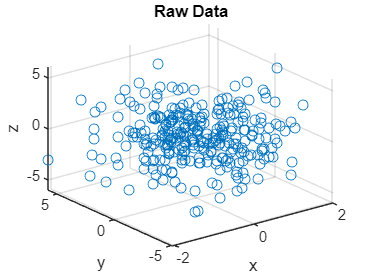

x = X(:,1);
y = X(:,2);
z = X(:,3);
fig1 = figure;
scatter3(x,y,z);
xlabel('x');
ylabel('y');
zlabel('z');
title('Raw Data')

## Perform PCA using SVD

We are going to use Singular Value Decomposition (SVD) to perform Principal Component Analysis (PCA)

First we do the SVD

[U,S,V] = svd(X, 0);

Choose how many dimensions to "keep"

k = 2;
V2 = V(:,1:k);

Perform PCA

P = X*V2;

## Visualize PCA results

p1 and p2 are the first two principal components.

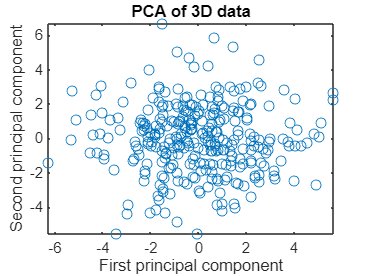

p1 = P(:,1);
p2 = P(:,2);
fig2 = figure;
plot(p1, p2, 'o');
xlabel('First principal component')
ylabel('Second principal component')
title('PCA of 3D data');

## Compute the percentage of the variance kept

varMat = S.^2;
variances = diag(varMat);
sumVariances = sum(variances);
percentages = 100*variances/sumVariances

percentages =    52.8278
   46.9313
    0.2409


# CCA Example for DSFEII

Perform CCA on the carbig dataset

load fisheriris.mat;

x = X(:,1);
y = X(:,2);
z = X(:,3);
fig1 = figure;
scatter3(x,y,z);
xlabel('x');
ylabel('y');
zlabel('z');
title('Raw Data')